clear; clc; close all;
%% ============================================================
%  1) DATOS DE PARTIDA Y DIMENSIONAMIENTO
%  ============================================================
% --- Producción objetivo ---
P_BHET_anual = 1000;          % kg BHET / año
dias_op      = 250;           % días/año (5 días·sem × 50 sem)
lotes_dia    = 3;             % lotes/día (turnos 8 h)
lotes_ano    = dias_op * lotes_dia;     % 750 lotes/año

% --- Rendimientos teóricos ---
yield_reaccion    = 0.95;          % conversión PET → BHET en reacción
yield_purif  = 0.95;          % rendimiento de la separación

% --- Pesos moleculares ---
Mw_PET   = 192.17;            % g/mol PET
Mw_BHET  = 254.24;            % g/mol BHET
Mw_EG    = 62.07;             % g/mol EG
f_esteq  = Mw_PET / Mw_BHET;  % g PET / g BHET (ideal)

% --- Carga másica del reactor ---
ratio_EG_PET = 5.0;           % EG:PET w/w
cat_wt       = 1;           % wt.% Zn(OAc)2 sobre PET 
C_PET_load   = 80;            % g PET / L mezcla líquida

% --- Cálculo masa por lote ---
m_BHET_lote = (P_BHET_anual * 1000) / lotes_ano;        % g BHET/lote
m_PET_lote  = m_BHET_lote * f_esteq / (yield_reaccion*yield_purif);  % g PET/lote
m_EG_lote   = m_PET_lote * ratio_EG_PET;                % g EG/lote
m_cat_lote  = m_PET_lote * cat_wt/100;                  % g cat/lote
m_tot_lote  = (m_PET_lote + m_EG_lote + m_cat_lote)/1000 % kg/lote

m_tot_lote = 6.7672


V_L = m_PET_lote / C_PET_load;      % L líquido por lote

% --- Geometría del reactor (factor de llenado 0,80; H/D = 1,5) ---
filling = 0.80;
V_R_min = V_L / filling;            % L (mínimo necesario)
V_R     = 20;                       % L — tamaño nominal
HD      = 1.5;
D_R     = ((4*V_R*1e-3)/(pi*HD))^(1/3);     % m
H_R     = HD * D_R;                          % m
H_L     = V_L*1e-3 / (pi*D_R^2/4);           % m altura de líquido
A_camisa   = pi*D_R*H_L + pi*D_R^2/4;           % m² lateral

% --- Concentración inicial de PET (mol/L) ---
Cs0 = (m_PET_lote / Mw_PET) / V_L;           % mol/L

%% ============================================================
%  2) PARÁMETROS CINÉTICOS DEL MODELO EXPERIMENTAL
%  ============================================================
T_ref = 170 + 273.15;                        % K
k_ref = [5.17e-4, 0.06, 0.0010, 0.039, 2.88e-7];   % min⁻¹ 
Ea    = [180e3,  158e3, 57e3,   37e3,  5e3];        % J/mol
R     = 8.314;                               % J/(mol·K)

% Parámetros catalíticos y de solvatación
p_kin.alpha = 0.51;
p_kin.beta  = 5.43e-6;
p_kin.S1    = 27.6;
p_kin.ratio = ratio_EG_PET;
p_kin.k_ref = k_ref;
p_kin.Ea    = Ea;
p_kin.T_ref = T_ref;

%% ============================================================
%  3) PARÁMETROS DEL BALANCE DE ENERGÍA (industrial)
%  ============================================================
% Cp ponderado por masa (Cp_i constante a 190 °C)
Cp_PET = 1500;       % J/(kg·K)  
Cp_EG  = 2900;       % J/(kg·K)  
Cp_cat = 1200;       % J/(kg·K) 
w_PET  = m_PET_lote/(m_tot_lote*1000);
w_EG   = m_EG_lote /(m_tot_lote*1000);
w_cat  = m_cat_lote/(m_tot_lote*1000);
Cp_mix = w_PET*Cp_PET + w_EG*Cp_EG + w_cat*Cp_cat   % J/(kg·K)

Cp_mix = 2.6521e+03


% Calor de reacción endotérmico 
DH_r   = 55e3;       % J/mol BHET

% Transferencia de calor camisa
U      = 500;        % W/(m²·K)  
T_HTF  = 220 + 273.15;      % K  
T_set  = 190 + 273.15;      % K 

% Empaquetado de parámetros para el integrador
p_ind = p_kin;
p_ind.cat   = cat_wt;
p_ind.V_L   = V_L;
p_ind.m_tot = m_tot_lote;
p_ind.Cp    = Cp_mix;
p_ind.DH_r  = DH_r;
p_ind.U     = U;
p_ind.A     = A_camisa;
p_ind.T_HTF = T_HTF;
p_ind.T_set = T_set;
p_ind.Mw_BHET = Mw_BHET;

%% ============================================================
%  4) RESUMEN DE DIMENSIONAMIENTO
%  ============================================================
fprintf('=========================================================\n');

fprintf(' DIMENSIONAMIENTO DESDE OBJETIVO 1 000 kg BHET/año        \n');

 DIMENSIONAMIENTO DESDE OBJETIVO 1 000 kg BHET/año        


fprintf('=========================================================\n');

fprintf('  Producción objetivo .........: %.0f kg BHET/año\n', P_BHET_anual);

  Producción objetivo .........: 1000 kg BHET/año


fprintf('  Días operativos / año .......: %d\n', dias_op);

  Días operativos / año .......: 250


fprintf('  Lotes / día .................: %d\n', lotes_dia);

  Lotes / día .................: 3


fprintf('  Lotes / año .................: %d\n', lotes_ano);

  Lotes / año .................: 750


fprintf('  Yield reacción × purificación: %.0f %% × %.0f %% = %.1f %%\n', ...
        yield_reaccion*100, yield_purif*100, yield_reaccion*yield_purif*100);

  Yield reacción × purificación: 95 % × 95 % = 90.2 %


fprintf('---------------------------------------------------------\n');

---------------------------------------------------------


fprintf(' MASA POR LOTE                                             \n');

 MASA POR LOTE                                             


fprintf('  PET     : %7.1f g\n', m_PET_lote);

  PET     :  1116.7 g


fprintf('  EG      : %7.1f g  (ratio %g:1 w/w)\n', m_EG_lote, ratio_EG_PET);

  EG      :  5583.5 g  (ratio 5:1 w/w)


fprintf('  Cat     : %7.1f g  (%.1f wt.%% sobre PET)\n', m_cat_lote, cat_wt);

  Cat     :    67.0 g  (6.0 wt.% sobre PET)


fprintf('  Total   : %7.3f kg\n', m_tot_lote);

  Total   :   6.767 kg


fprintf('  BHET obj: %7.1f g/lote (%.0f kg/lote)\n', m_BHET_lote, m_BHET_lote/1000);

  BHET obj:  1333.3 g/lote (1 kg/lote)


fprintf('---------------------------------------------------------\n');

---------------------------------------------------------


fprintf(' GEOMETRÍA DEL REACTOR                                     \n');

 GEOMETRÍA DEL REACTOR                                     


fprintf('  V líquido (carga 80 g PET/L): %.2f L\n', V_L);

  V líquido (carga 80 g PET/L): 13.96 L


fprintf('  V reactor mínimo (80 %% lleno): %.2f L\n', V_R_min);

  V reactor mínimo (80 % lleno): 17.45 L


fprintf('  V reactor normalizado .......: %d L\n', V_R);

  V reactor normalizado .......: 20 L


fprintf('  D = %.1f mm | H = %.1f mm | H/D = %.1f\n', D_R*1000, H_R*1000, HD);

  D = 257.0 mm | H = 385.5 mm | H/D = 1.5


fprintf('  H líquido = %.1f mm | A camisa = %.4f m²\n', H_L*1000, A_camisa);

  H líquido = 269.1 mm | A camisa = 0.2691 m²


fprintf('---------------------------------------------------------\n');

---------------------------------------------------------


fprintf(' BALANCE DE ENERGÍA                                       \n');

 BALANCE DE ENERGÍA                                       


fprintf('  Cp mezcla ponderado .........: %.0f J/(kg·K)\n', Cp_mix);

  Cp mezcla ponderado .........: 2652 J/(kg·K)


fprintf('  ΔH reacción ..: %.0f kJ/mol BHET\n', DH_r/1000);

  ΔH reacción ..: 55 kJ/mol BHET


fprintf('  U camisa (Perry, extr. alto) .: %.0f W/(m²·K)\n', U);

  U camisa (Perry, extr. alto) .: 500 W/(m²·K)


fprintf('  Setpoint reactor / fluido HTF: %.0f / %.0f °C\n', ...
        T_set-273.15, T_HTF-273.15);

  Setpoint reactor / fluido HTF: 190 / 220 °C


fprintf('  U·A (capacidad camisa) ......: %.0f W/K (%.2f kW por 10 °C ΔT)\n', ...
        U*A_camisa, U*A_camisa*10/1000);

  U·A (capacidad camisa) ......: 135 W/K (1.35 kW por 10 °C ΔT)


fprintf('=========================================================\n\n');


%% ============================================================
%  5) REPRODUCCIÓN DE LAS FIGURAS DEL PAPER A 190 °C
%  ============================================================
% Validación isoterma del modelo cinético
% Cargas de catalizador: 0,6 / 3,0 / 6,0 wt.%.
T_lab = 190 + 273.15;
k_lab = k_ref .* exp((Ea/R) .* (1/T_ref - 1/T_lab));

% Escala de laboratorio del paper (V = 0,25 L, 20 g PET)
V_L_lab = 0.25;
mPET_lab = 20;        % g
Cs0_lab  = (mPET_lab/Mw_PET) / V_L_lab;       % mol/L
y0_lab   = [Cs0_lab; 0; 0];

cat_vec = [0.6, 3.0, 6.0];                    % wt.%
labels_cat = {'0,6 wt.% cat (Fig. 7a)', ...
              '3,0 wt.% cat (Fig. 7b)', ...
              '6,0 wt.% cat (Fig. 7c)'};
t_end_lab = 300;                              % min

t_lab = cell(3,1); y_lab = cell(3,1);
for i = 1:3
    pi_set       = p_kin;
    pi_set.cat   = cat_vec(i);
    pi_set.k1=k_lab(1); pi_set.k2=k_lab(2); pi_set.k3=k_lab(3);
    pi_set.k4=k_lab(4); pi_set.k5=k_lab(5);
    [t_lab{i}, y_lab{i}] = ode45(@(t,y) PET_EDOs(t,y,pi_set), ...
                                 [0 t_end_lab], y0_lab);
end

%% ========================================================================
%  6) SIMULACIÓN DEL REACTOR INDUSTRIAL (BALANCE MASA +ENERGIA  ACOPLADO)
%  ========================================================================
% Estado: [Cs ; Ci ; Cb ; T] con T en K. Inicio a 25 °C.
T0       = 25 + 273.15;
y0_ind   = [Cs0; 0; 0; T0];
t_end_ind = 300;                              % min

[t_ind, y_ind] = ode45(@(t,y) PET_EDOs_termico(t,y,p_ind), ...
                       [0 t_end_ind], y0_ind);

Cs_ind = y_ind(:,1);
Ci_ind = y_ind(:,2);
Cb_ind = y_ind(:,3);
T_ind  = y_ind(:,4);
T_indC = T_ind - 273.15;

% Recálculo de los flujos térmicos a posteriori
nT = numel(t_ind);
Q_reaccion_kW = zeros(nT,1);
Q_camisa_kW = zeros(nT,1);
for j = 1:nT
    Tj = T_ind(j);
    kj = k_ref .* exp((Ea/R) .* (1/T_ref - 1/Tj));
    r3 = kj(3)*Ci_ind(j);
    r4 = kj(4)*Ci_ind(j)*(p_ind.cat^p_ind.beta);
    r5 = kj(5)*Cb_ind(j)*exp(p_ind.S1*(1/p_ind.ratio - 1/5));
    rB_neta_s = (r3 + r4 - r5)/60;            % mol/(L·s)
    nB_dot    = rB_neta_s * V_L;              % mol/s
    Q_reaccion_kW(j) = -DH_r * nB_dot / 1000;      % kW (negativo: endotérmico)
    if Tj >= T_set
        Q_camisa_kW(j) = 0;
    else
        Q_camisa_kW(j) = U*A_camisa*(T_HTF - Tj)/1000;   % kW
    end
end

%% ==========================================
%  7) INDICADORES DE PROCESO (LOTE + ANUAL)
%  ==========================================
mBHET_obtenido_g = Cb_ind(end) * V_L * Mw_BHET;            % g/lote
yield_real       = 100 * (mBHET_obtenido_g / m_BHET_lote * yield_reaccion*yield_purif);
X_PET_final      = 100 * (1 - Cs_ind(end)/Cs0);

% Energía
E_camisa_kJ = trapz(t_ind*60, Q_camisa_kW*1000) / 1000;   % t en s → kJ
E_anual_GJ = E_camisa_kJ * lotes_ano / 1e6;            % GJ/año

fprintf(' RESULTADOS DE LA SIMULACIÓN INDUSTRIAL                   \n');

 RESULTADOS DE LA SIMULACIÓN INDUSTRIAL                   


fprintf('---------------------------------------------------------\n');

---------------------------------------------------------


fprintf('  Conversión final de PET ......: %.1f %%\n', X_PET_final);

  Conversión final de PET ......: 100.0 %


fprintf('  BHET en reactor (mol/L) .......: %.3f\n', Cb_ind(end));

  BHET en reactor (mol/L) .......: 0.416


fprintf('  BHET por lote (sin separación): %.0f g\n', mBHET_obtenido_g);

  BHET por lote (sin separación): 1477 g


fprintf('  Tiempo hasta T = 188 °C .......: %.1f min\n', ...
        interp1(T_indC, t_ind, 188, 'linear', NaN));

  Tiempo hasta T = 188 °C .......: 6.5 min


fprintf('  Q máx camisa (calentamiento) ..: %.2f kW\n', max(Q_camisa_kW));

  Q máx camisa (calentamiento) ..: 26.24 kW


fprintf('  Q reacción (pico endotérmico) .: %.3f kW\n', min(Q_reaccion_kW));

  Q reacción (pico endotérmico) .: -0.276 kW


fprintf('  Energía aportada por la camisa: %.0f kJ/lote\n', E_camisa_kJ);

  Energía aportada por la camisa: 3385 kJ/lote


fprintf('  Energía térmica total anual ..: %.2f GJ/año\n', E_anual_GJ);

  Energía térmica total anual ..: 2.54 GJ/año


fprintf('---------------------------------------------------------\n');

---------------------------------------------------------


fprintf(' RECURSOS ANUALES                                         \n');

 RECURSOS ANUALES                                         


fprintf('  PET procesado ................: %.0f kg/año\n', m_PET_lote*lotes_ano/1000);

  PET procesado ................: 838 kg/año


fprintf('  EG total (sin recirculación) ..: %.0f kg/año\n', m_EG_lote*lotes_ano/1000);

  EG total (sin recirculación) ..: 4188 kg/año


fprintf('  Catalizador Zn(OAc)2 ..........: %.1f kg/año\n', m_cat_lote*lotes_ano/1000);

  Catalizador Zn(OAc)2 ..........: 50.3 kg/año


fprintf('=========================================================\n\n');

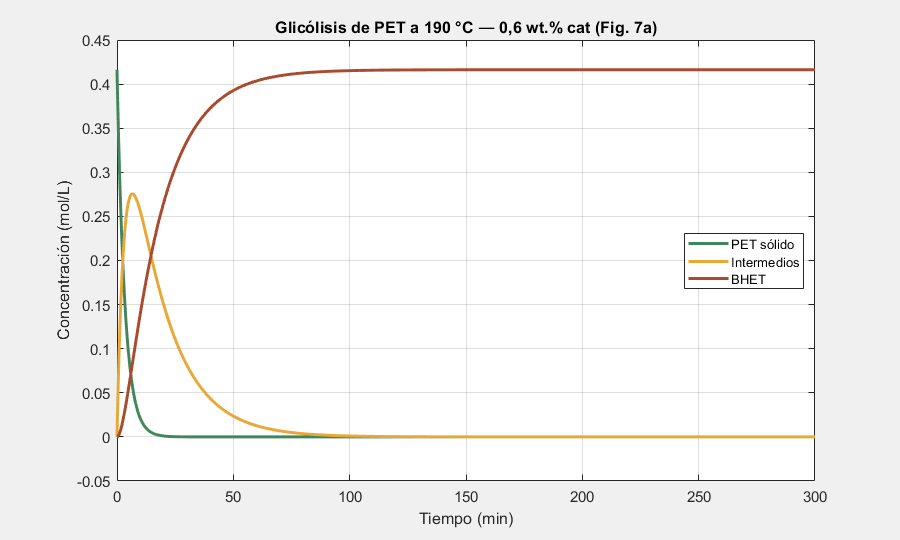

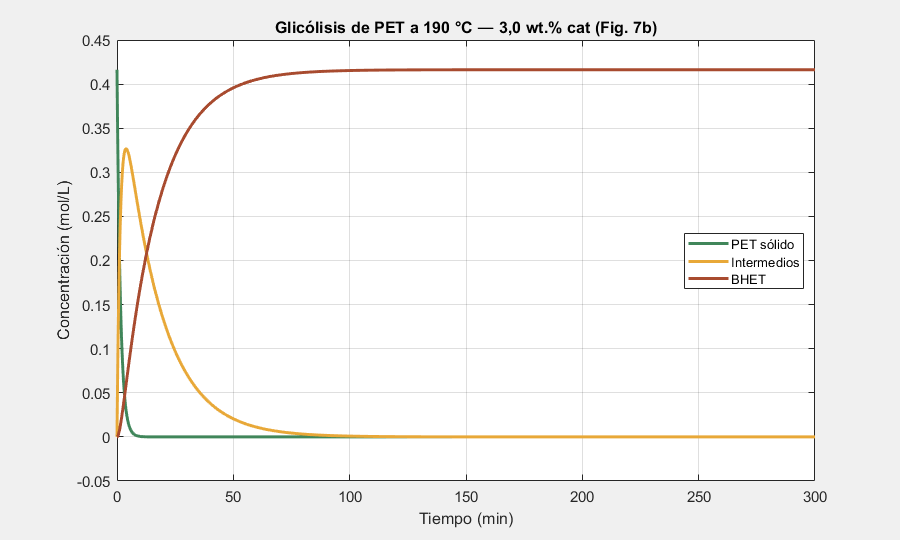

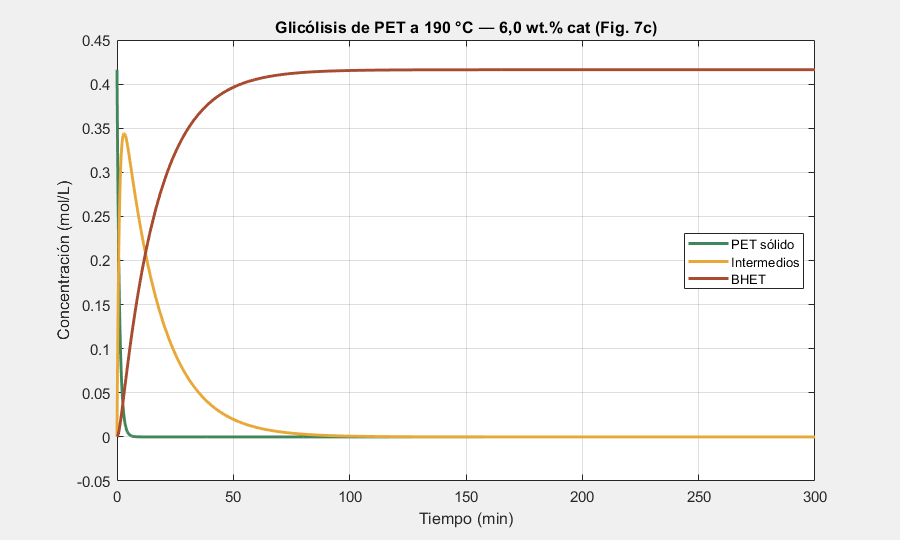


% Guardado de variables clave
save('C:/Users/molto/TFG/PET_resultados.mat', ...
     't_lab','y_lab','cat_vec','t_ind','y_ind','T_indC', ...
     'Q_reaccion_kW','Q_camisa_kW','-v7');

%% ==============
%  8) GRÁFICAS
%  ==============
set(0,'DefaultAxesFontName','Helvetica');
set(0,'DefaultAxesFontSize',11);
set(0,'DefaultTextFontName','Helvetica');

% Colores
VERDE = [ 64 134  90]/255;     % PET
AMARILLO  = [232 168  56]/255;     % Intermedios
ROJO   = [168  75  47]/255;     % BHET
AZUL  = [ 12  78  84]/255;     % Térmico

% --- 8.1 Reproducción a 190 °C ---
for i = 1:3
    fh = figure('visible','on','Position',[100 100 900 540]);
    plot(t_lab{i}, y_lab{i}(:,1), '-', 'Color', VERDE, 'LineWidth', 2.2); hold on;
    plot(t_lab{i}, y_lab{i}(:,2), '-', 'Color', AMARILLO,  'LineWidth', 2.2);
    plot(t_lab{i}, y_lab{i}(:,3), '-', 'Color', ROJO,   'LineWidth', 2.2);
    xlabel('Tiempo (min)');
    ylabel('Concentración (mol/L)');
    title(sprintf('Glicólisis de PET a 190 °C — %s', labels_cat{i}));
    legend({'PET sólido','Intermedios','BHET'}, 'Location','East');
    grid on; xlim([0 300]);
    fname = sprintf('C:/Users/molto/TFG/cat_x%.0f.png', cat_vec(i)*10);
    print(fh, fname, '-dpng', '-r150');
end

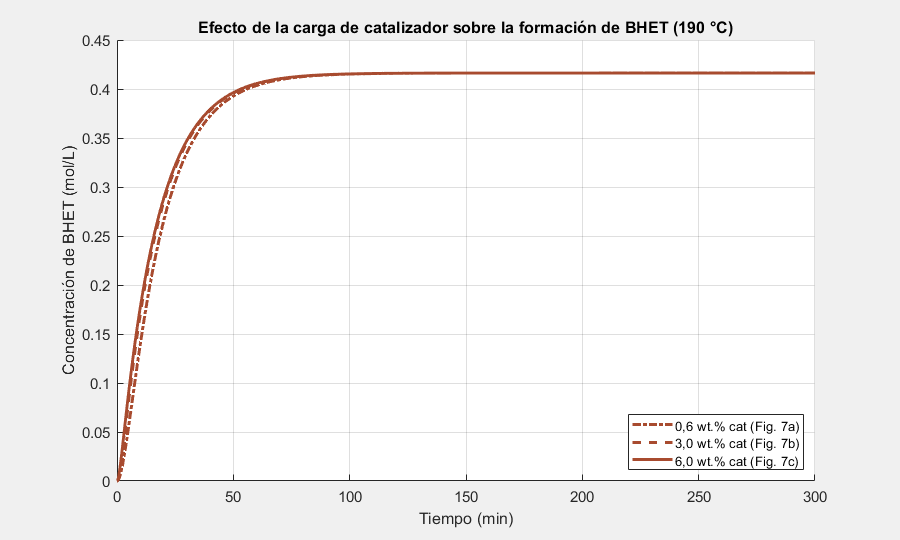


% --- 8.2 Comparativa BHET vs t (efecto del catalizador) ---
fh = figure('visible','on','Position',[100 100 900 540]);
ls = {'-.','--','-'};
hold on;
for i = 1:3
    plot(t_lab{i}, y_lab{i}(:,3), ls{i}, 'Color', ROJO, 'LineWidth', 2.2);
end
xlabel('Tiempo (min)');
ylabel('Concentración de BHET (mol/L)');
title('Efecto de la carga de catalizador sobre la formación de BHET (190 °C)');
legend(labels_cat, 'Location','SouthEast');
grid on; xlim([0 300]);
print(fh, 'C:/Users/molto/TFG/comparativa_cat.png', '-dpng', '-r150');

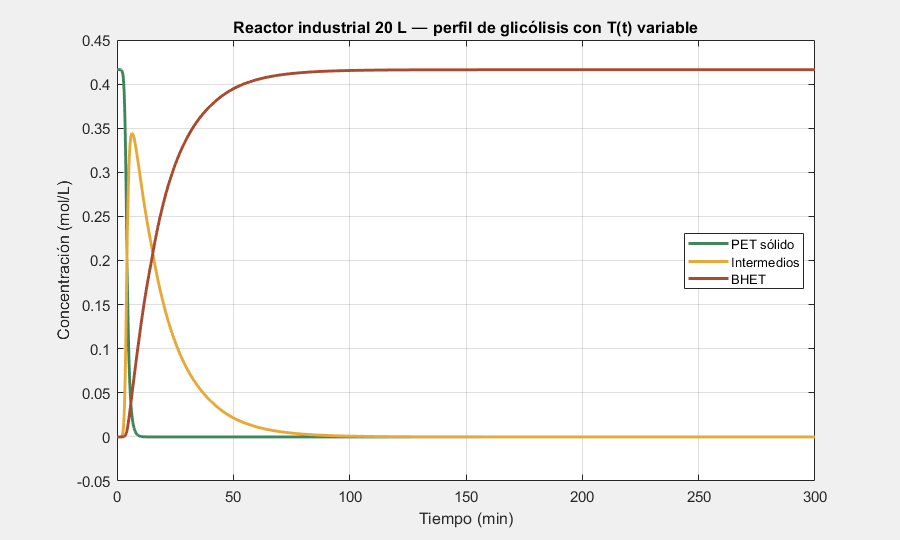


% --- 8.3 Reactor industrial: perfil de concentraciones ---
fh = figure('visible','on','Position',[100 100 900 540]);
plot(t_ind, Cs_ind, '-', 'Color', VERDE, 'LineWidth', 2.2); hold on;
plot(t_ind, Ci_ind, '-', 'Color', AMARILLO,  'LineWidth', 2.2);
plot(t_ind, Cb_ind, '-', 'Color', ROJO,   'LineWidth', 2.2);
xlabel('Tiempo (min)');
ylabel('Concentración (mol/L)');
title('Reactor industrial 20 L — perfil de glicólisis con T(t) variable');
legend({'PET sólido','Intermedios','BHET'}, 'Location','East');
grid on; xlim([0 300]);
print(fh, 'C:/Users/molto/TFG/C_reactor.png', '-dpng', '-r150');

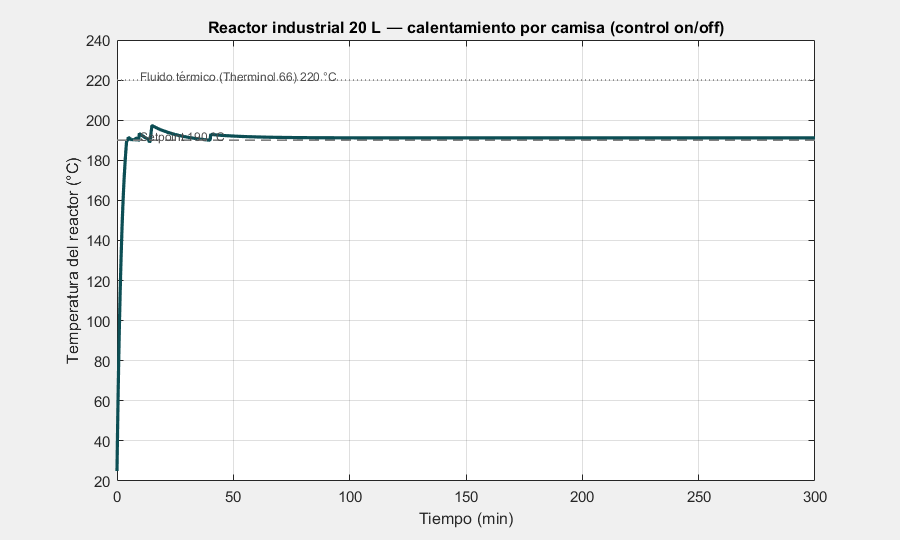


% --- 8.4 Reactor industrial: perfil de temperatura ---
fh = figure('visible','on','Position',[100 100 900 540]);
plot(t_ind, T_indC, '-', 'Color', AZUL, 'LineWidth', 2.4); hold on;
plot([0 t_end_ind], [190 190], '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 1.2);
plot([0 t_end_ind], [220 220], ':',  'Color', [0.5 0.5 0.5], 'LineWidth', 1.2);
text(10, 192, 'Setpoint 190 °C', 'FontSize', 9, 'Color', [0.3 0.3 0.3]);
text(10, 222, 'Fluido térmico (Therminol 66) 220 °C', ...
     'FontSize', 9, 'Color', [0.3 0.3 0.3]);
xlabel('Tiempo (min)');
ylabel('Temperatura del reactor (°C)');
title('Reactor industrial 20 L — calentamiento por camisa (control on/off)');
grid on; xlim([0 t_end_ind]); ylim([20 240]);
print(fh, 'C:/Users/molto/TFG/T_reactor.png', '-dpng', '-r150');

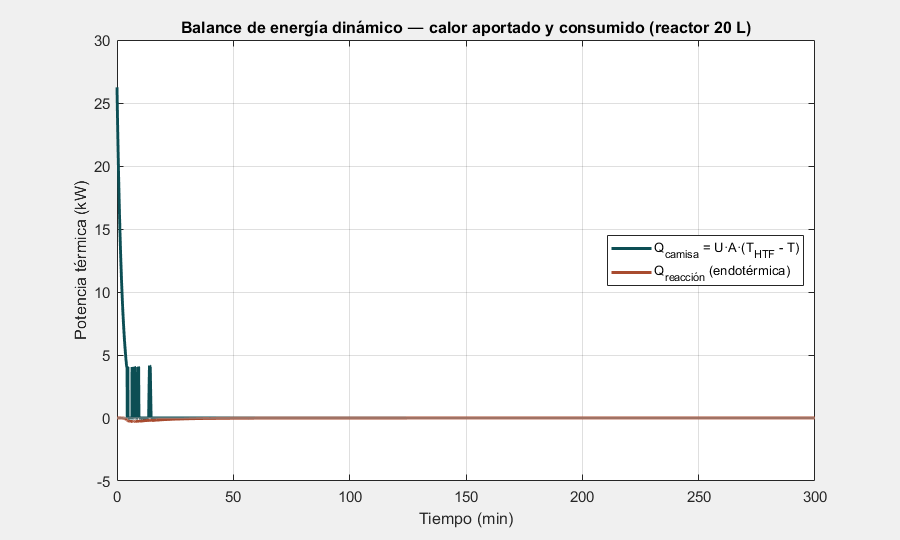


% --- 8.5 Reactor industrial: flujos térmicos ---
fh = figure('visible','on','Position',[100 100 900 540]);
plot(t_ind, Q_camisa_kW, '-', 'Color', AZUL, 'LineWidth', 2.2); hold on;
plot(t_ind, Q_reaccion_kW, '-', 'Color', ROJO,  'LineWidth', 2.2);
plot([0 t_end_ind], [0 0], '-', 'Color', [0.6 0.6 0.6], 'LineWidth', 0.8);
xlabel('Tiempo (min)');
ylabel('Potencia térmica (kW)');
title('Balance de energía dinámico — calor aportado y consumido (reactor 20 L)');
legend({'Q_{camisa} = U·A·(T_{HTF} - T)', ...
        'Q_{reacción} (endotérmica)'}, 'Location','East');
grid on; xlim([0 t_end_ind]);
print(fh, 'C:/Users/molto/TFG/Q_reactor.png', '-dpng', '-r150');

function dydt = PET_EDOs(t, y, p)

    Cs = y(1); Ci = y(2); Cb = y(3);

    r1 = p.k1 * Cs;
    r2 = p.k2 * Cs * (p.cat^p.alpha);
    r3 = p.k3 * Ci;
    r4 = p.k4 * Ci * (p.cat^p.beta);
    r5 = p.k5 * Cb * exp(p.S1*(1/p.ratio - 1/5));   % reacción inversa

    dCs = -r1 - r2;
    dCi =  r1 + r2 - r3 - r4 + r5;
    dCb =  r3 + r4 - r5;

    dydt = [dCs; dCi; dCb];
end

function dydt = PET_EDOs_termico(t, y, p)

    Cs = y(1); Ci = y(2); Cb = y(3); T = y(4);

    R = 8.314;

    % --- 1) Constantes cinéticas a T(t) ---
    k = p.k_ref .* exp((p.Ea/R) .* (1/p.T_ref - 1/T));

    % --- 2) Velocidades de reacción ---
    r1 = k(1)*Cs;
    r2 = k(2)*Cs*(p.cat^p.alpha);
    r3 = k(3)*Ci;
    r4 = k(4)*Ci*(p.cat^p.beta);
    r5 = k(5)*Cb*exp(p.S1*(1/p.ratio - 1/5));

    dCs = -r1 - r2;
    dCi =  r1 + r2 - r3 - r4 + r5;
    dCb =  r3 + r4 - r5;

    % --- 3) Balance de energía ---
    rB_neta_min = r3 + r4 - r5;          % mol/(L·min)
    rB_neta_s   = rB_neta_min/60;        % mol/(L·s)
    nB_dot      = rB_neta_s * p.V_L;     % mol/s   (V_L en L)

    % Calor consumido por la reacción (endotérmica ⇒ Q_rxn < 0)
    Q_consumido = -p.DH_r * nB_dot;            % W

    % Camisa con control on/off al setpoint
    if T >= p.T_set
        Q_camisa = 0;                       % válvula cerrada
    else
        Q_camisa = p.U * p.A * (p.T_HTF - T);   % W
    end

    % dT/dt en K/s, convertimos a K/min para integrar con t en minutos
    dT_dt_s   = (Q_consumido + Q_camisa) / (p.m_tot * p.Cp);   % K/s
    dT_dt_min = dT_dt_s * 60;                          % K/min

    dydt = [dCs; dCi; dCb; dT_dt_min];
end

